# Obstacle-Free Path Planning Using Hybrid A Star

Plan a collision-free path for a vehicle through a parking lot by using the Hybrid A* algorithm.

## Create and Assign Map to State Validator

Load the cost values of cells in the vehicle costmap of a parking lot.

%imageCropped = imread('C:\Users\Tejal\Downloads\Office.pgm');
%imageCropped = image(750:1250,750:1250);
%imshow(imageCropped)

PGM values are expressed from 0 to 255 as `uint8`. Normalize these values by converting the cropped image to `double` and dividing each cell by 255. This image shows obstacles as values close to 0. Subtract the normalized image from 1 to get occupancy values with 1 representing occupied space.

imageNorm = double(imageCropped)/255;
imageOccupancy = 1 - imageNorm;

Create the `occupancyMap` object using an adjusted map image. The imported map resolution is 20 cells per meter.

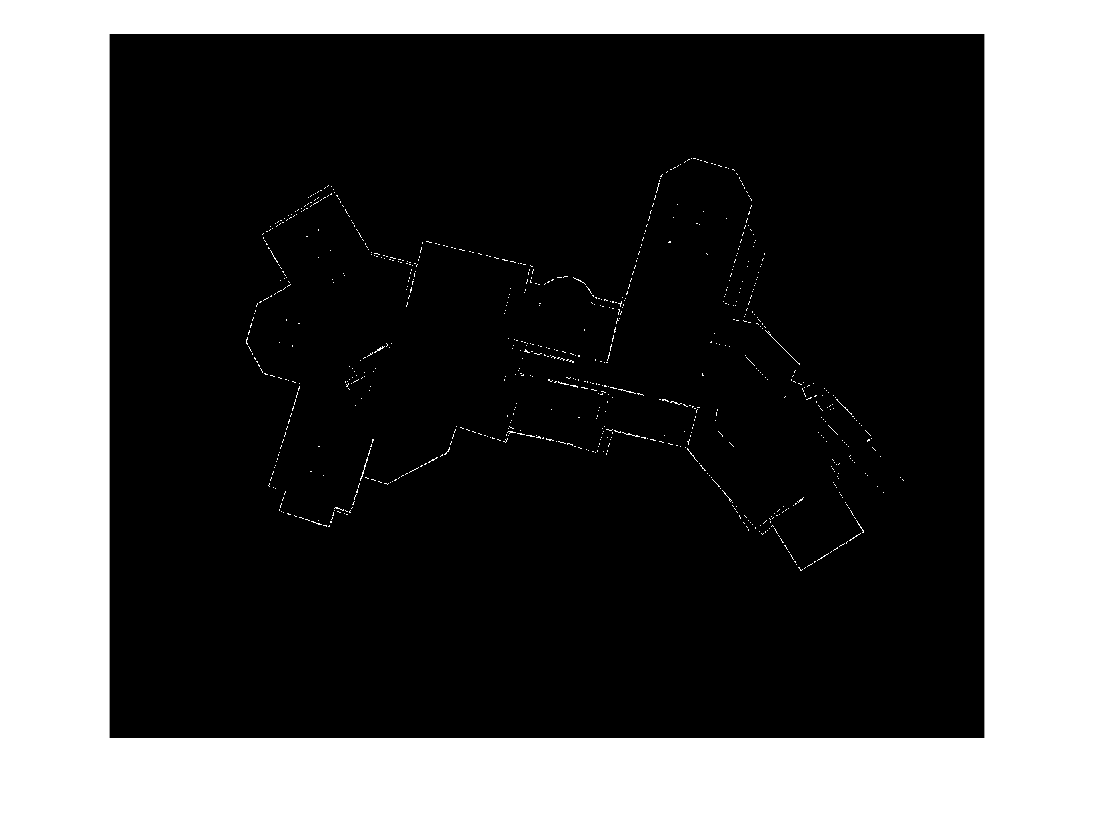

%map = occupancyMap(imageOccupancy,20);
image = imread('C:\Users\Tejal\Downloads\Office.pgm');
imageBW = image < 100;
imshow(imageBW)

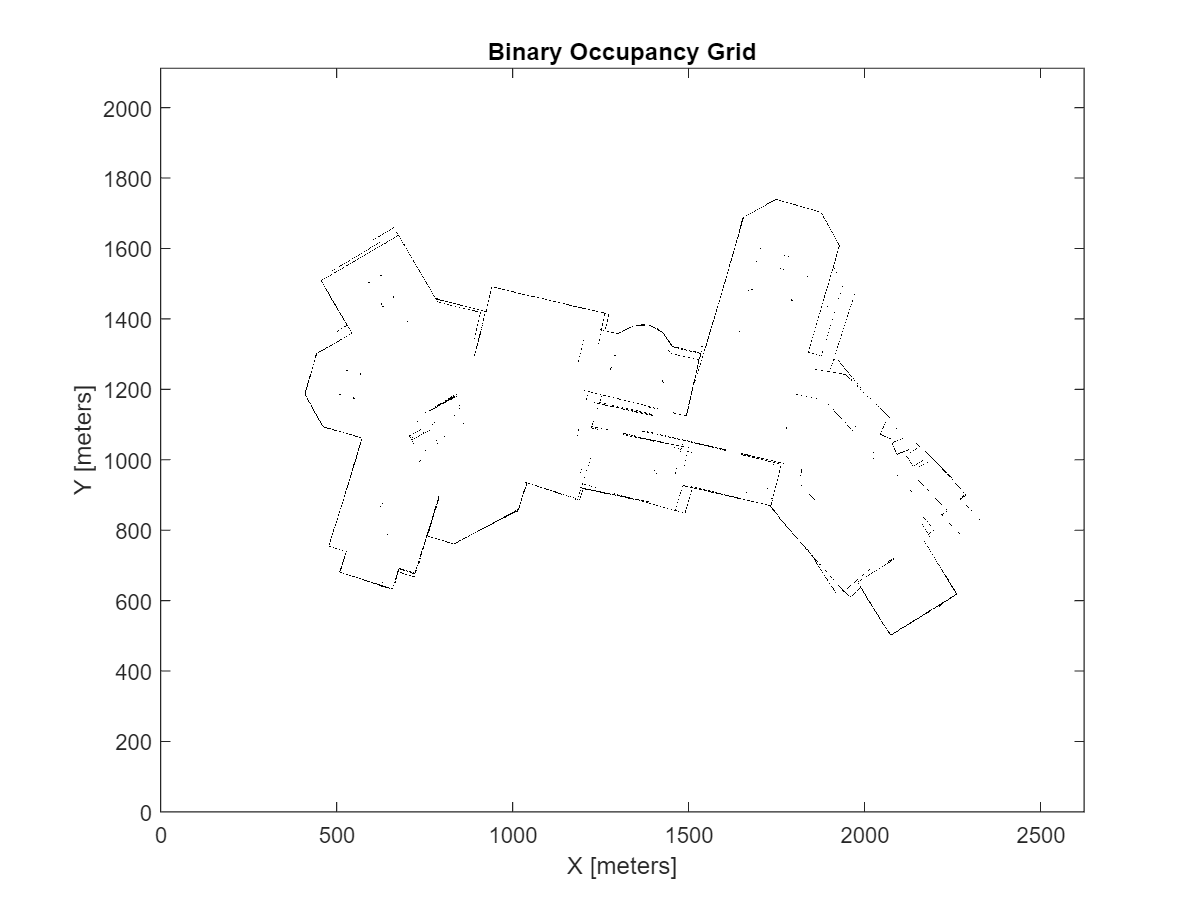

map = binaryOccupancyMap(imageBW);
show(map)

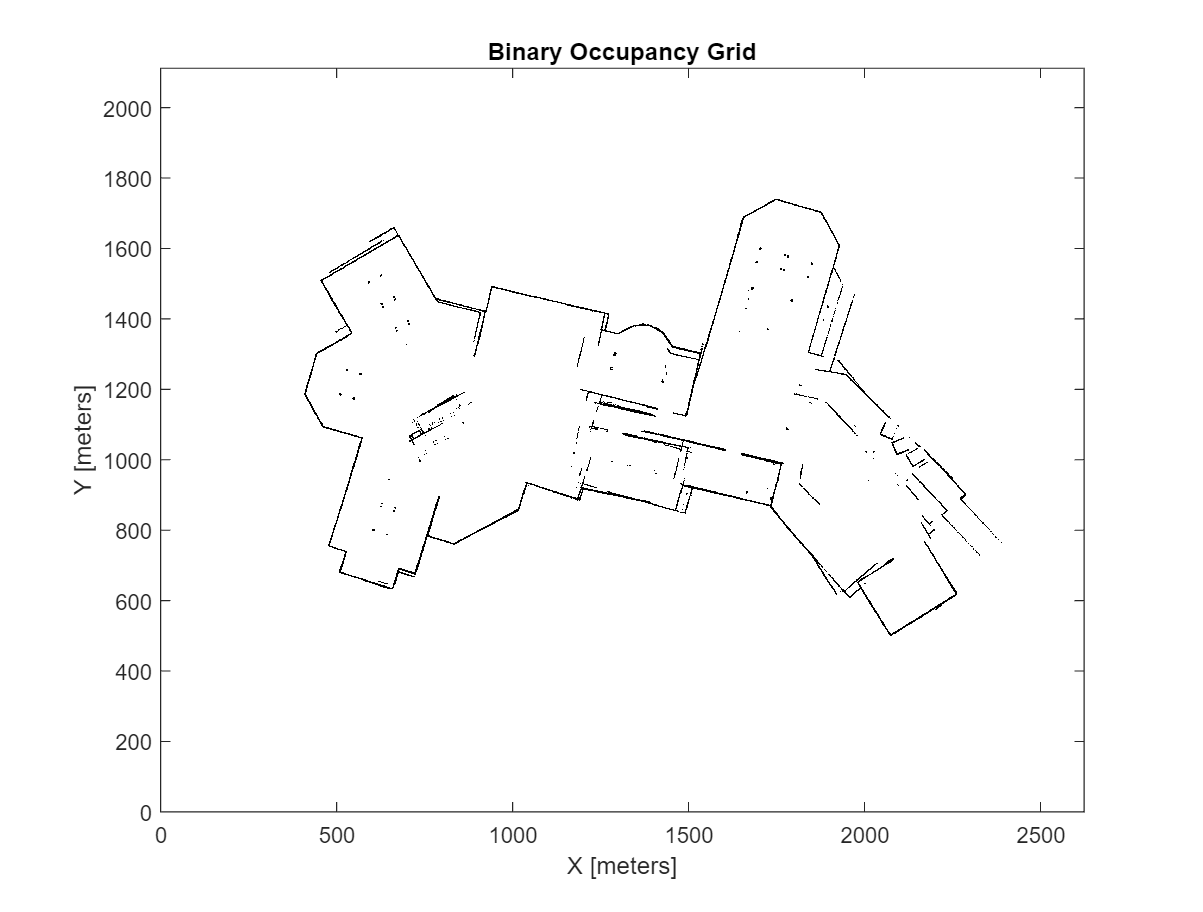

%save('mapturtle','map')
inflate(map,0.1)
show(map)

costmap = vehicleCostmap(map)

costmap =   vehicleCostmap with properties:

        FreeThreshold: 0.2000
    OccupiedThreshold: 0.6500
     CollisionChecker: [1×1 driving.costmap.InflationCollisionChecker]
             CellSize: 1
              MapSize: [2112 2624]
            MapExtent: [0 2624 0 2112]


%load cost % costVal

Create a [`binaryOccupancyMap`](docid:nav_ref#bunq527) with cost values.

%resolution = 3;
%map = binaryOccupancyMap(costVal,resolution);

Create a state space.

ss = stateSpaceSE2;

Update state space bounds to be the same as map limits.

ss.StateBounds = [map.XWorldLimits;map.YWorldLimits;[-pi pi]];

Create a state validator object for collision checking.

sv = validatorOccupancyMap(ss);

Assign the map to the state validator object.

sv.Map = map;

## Plan and Visualize Path

Initialize the [`plannerHybridAStar`](docid:nav_ref#object_plannerhybridastar) object with the state validator object. Specify the `MinTurningRadius` and `MotionPrimitiveLength` properties of the planner.

planner = plannerHybridAStar(sv, ...
                             MinTurningRadius=4, ...
                             MotionPrimitiveLength=6);

Define start and goal poses for the vehicle as [*x, y, theta*] vectors. *x* and *y* specify the position in meters, and *theta* specifies the orientation angle in radians.

startPose = [800 800 pi/2]; % [meters, meters, radians]
goalPose = [1200 1400 -pi/2];

Plan a path from the start pose to the goal pose.

refpath = plan(planner,startPose,goalPose,SearchMode='exhaustive');     

Visualize the path using show function.

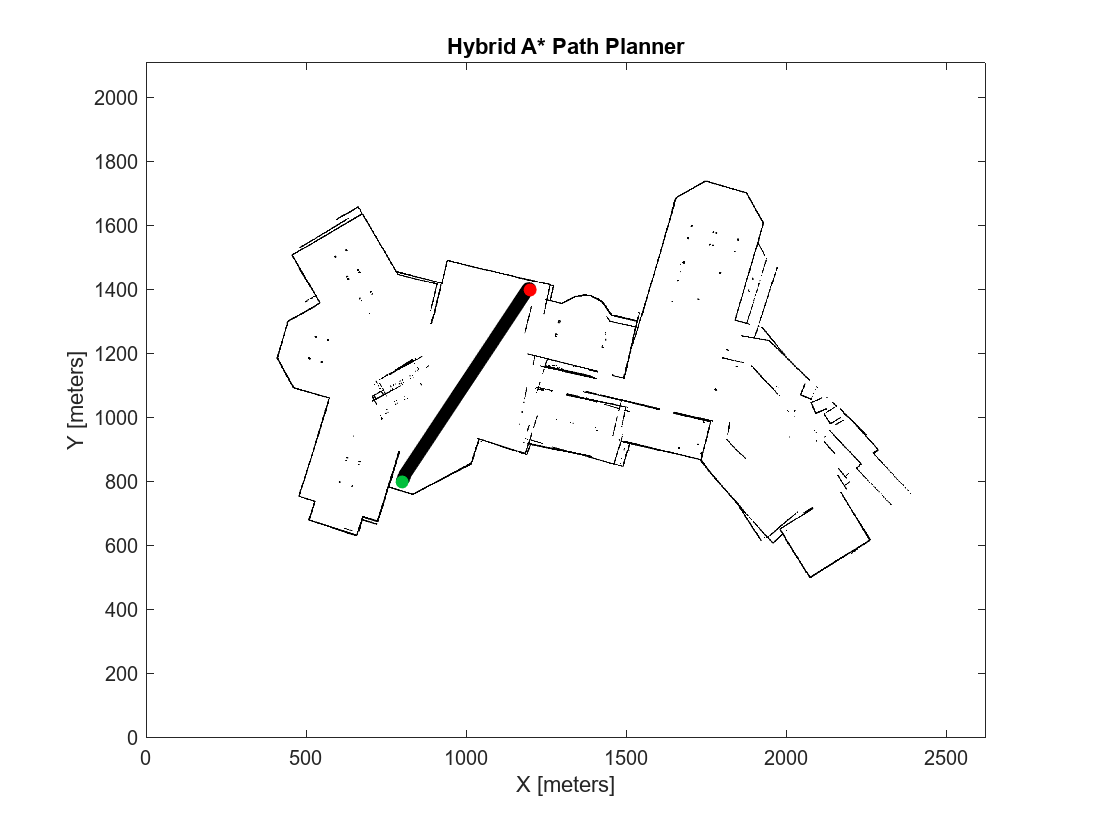

show(planner)

*Copyright 2019 The MathWorks, Inc.*